clear variables; close all; clc;

## Statistical analysis from simulation data

Load csv with simulation data

data = readtable("data.csv", "VariableNamingRule","preserve");

### Label users by skills

Here we can label pilots based on their licence or the flight hours or combination of those

#### Divide by Licenses

% data = divideByLicense(data);

#### Divide by Flight hours

data = divideByFlightHrs(data);

Lookup labeling

display(data)

data = 11×13 table
    pilot_id    age    flight_hrs     licenses      success     duration_secs    distance_m    max_speed_mps    avg_speed_mps    max_height_m    avg_height_m    overflown_people      skilled  
    ________    ___    __________    __________    _________    _____________    __________    _____________    _____________    ____________    ____________    ________________    ___________

       1         0        200        {'string'}    {'True' }         40            650.68         20.542            16.153            30.2           23.

### DEMO

### Overflown people

% var_title = 'Overflown people';

analyse and plot distribution for the 2 subsets

% analyseDistribution(data.overflown_people, data.skilled, strcat(var_title, '-original'));

generate data based on distributions from the subsets, analyse and plot

% [split, generated] = generateData(data, data.overflown_people, 200);
% analyseDistribution(generated, split, strcat(var_title, '-generated'));

split generated samples and perform tests

% skilled = generated(split=="Skilled");
% unskilled = generated(split=="Unskilled");
% perform_tests(skilled,unskilled);

Repeat for another variable

% var_title = 'duration secs';
% analyseDistribution(data.duration_secs, data.skilled, strcat(var_title,'-original'));
% 
% [split, generated] = generateData(data, data.duration_secs, 200);
% analyseDistribution(generated, split, strcat(var_title,'-generated'));
% skilled = generated(split=="Skilled");
% unskilled = generated(split=="Unskilled");
% perform_tests(skilled,unskilled);


...

### Generate expectation ranges on variables

We know that all skilled pilots have chosen path $P$, while all unskilled pilots have chosen path $P^*$. 

We also know that going for path $P$ takes expected time $E_{t}$ and overflown people $E_o$, while going for path $P^*$ takes expected time $E^*_{t}$ and overflown people $E^*_o$.

Ideally we know both $E_t \le E^*_t$ and $E_o \le E^*_o$ thanks to the design of the scenario, hence we can perform a t-test assuming unequal variance (left tail) on the duration secs and overflown people variables.

Pink path: longest & safest, 

Light blue path: shortest & most people

Dark blue path: medium length & most dangerous 4 payload (river)

TEST ON:

-duration secs (pink path takes longer)

-overflown people(pink path flies over less people)

-distance(pink path is the longest)

-average height(expert users take the drone low 4 safety)

-average speed(unexperts might start going full throttle)

(same reasoning for max height, max speed)

#### Duration Seconds

When chosing the pink path pilots will fly in expectation in a longer time, we either check users which have chosen the pink path versus other paths, or we assume experts pilots have chosen the pink one due to safety risks.

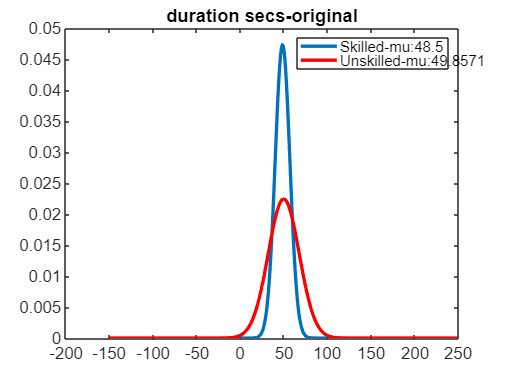

var_title = 'duration secs';                                                            % variable analysed
analyseDistribution(data.duration_secs, data.skilled, strcat(var_title,'-original'));   % analyse the distribution of original values

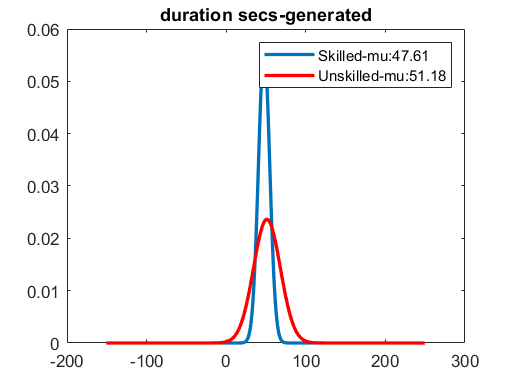

[split, generated] = generateData(data, data.duration_secs, 200);                       % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                  % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                  % subset division 1
unskilled = generated(split=="Unskilled");                                              % subset division 2
t_test_tail(skilled,unskilled,'right');                                                 % t-test tail right (x > y)

    "Null h:Equal mean/Alternative h:x > y"

    "Do not reject null hypothesis, p:0.97368"



#### Overflown people

When chosing the pink path pilots will fly in expectation over less people, we either check users which have chosen the pink path versus other paths, or we assume experts pilots have chosen the pink one due to safety risks.

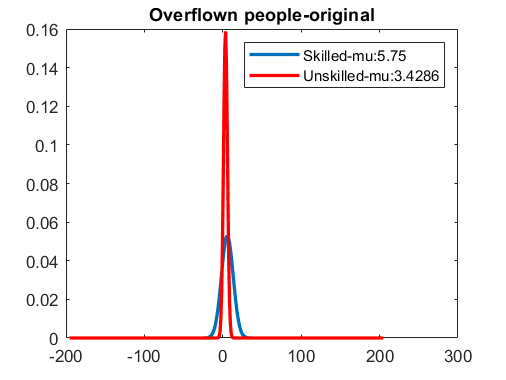

var_title = 'Overflown people';                                                            % variable analysed
analyseDistribution(data.overflown_people, data.skilled, strcat(var_title,'-original'));   % analyse the distribution of original values

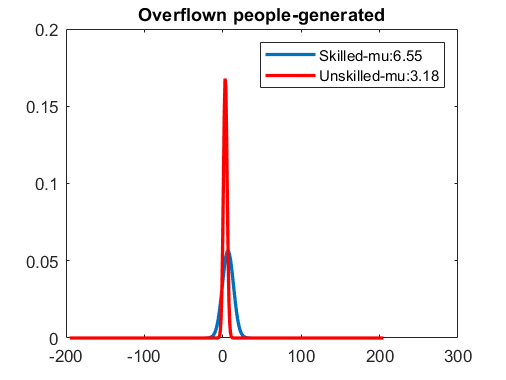

[split, generated] = generateData(data, data.overflown_people, 200);                       % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                     % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                     % subset division 1
unskilled = generated(split=="Unskilled");                                                 % subset division 2
t_test_tail(skilled,unskilled,'left');                                                     % t-test tail left (x < y)

    "Null h:Equal mean/Alternative h:x < y"

    "Do not reject null hypothesis, p:0.92433"



#### Distance meters

When chosing the pink path pilots will fly in expectation in a longer path, we either check users which have chosen the pink path versus other paths, or we assume experts pilots have chosen the pink one due to safety risks.

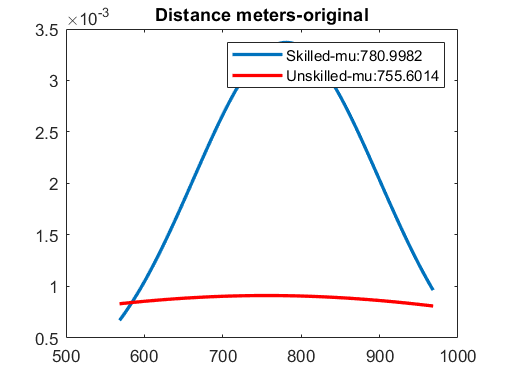

var_title = 'Distance meters';                                                            % variable analysed
analyseDistribution(data.distance_m, data.skilled, strcat(var_title,'-original'));        % analyse the distribution of original values

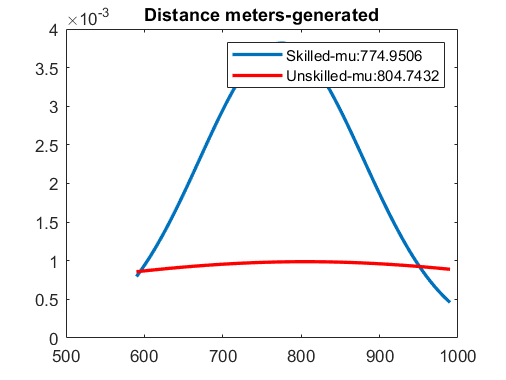

[split, generated] = generateData(data, data.distance_m, 200);                            % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                    % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                    % subset division 1
unskilled = generated(split=="Unskilled");                                                % subset division 2
t_test_tail(skilled,unskilled,'right');                                                   % t-test tail right (x > y)

    "Null h:Equal mean/Alternative h:x > y"

    "Do not reject null hypothesis, p:0.76202"



#### Average height

We assume skilled pilots will keep the drone at an average lower height for safety reasons

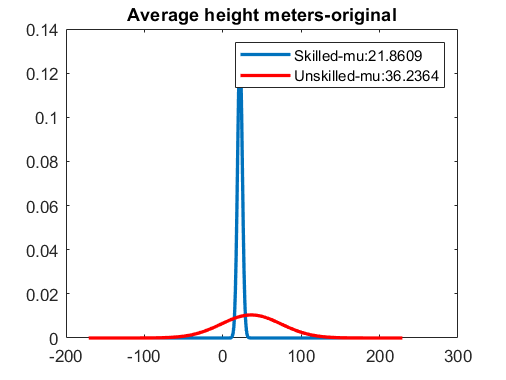

var_title = 'Average height meters';                                                        % variable analysed
analyseDistribution(data.avg_height_m, data.skilled, strcat(var_title,'-original'));        % analyse the distribution of original values

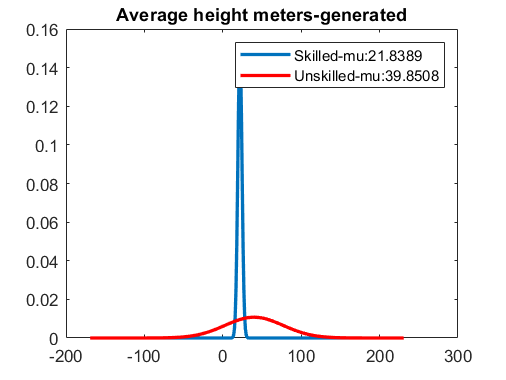

[split, generated] = generateData(data, data.avg_height_m, 200);                            % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                      % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                      % subset division 1
unskilled = generated(split=="Unskilled");                                                  % subset division 2
t_test_tail(skilled,unskilled,'left');                                                      % t-test tail left (x < y)

    "Null h:Equal mean/Alternative h:x < y"

    "Reject null hypothesis, p:1.2785e-06"



#### Maximum height

We assume skilled pilots will keep the drone at a lower maximum height for safety reasons

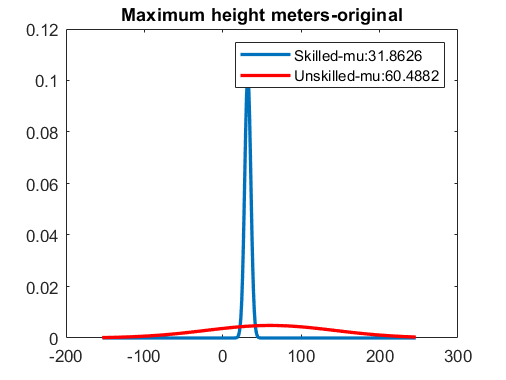

var_title = 'Maximum height meters';                                                        % variable analysed
analyseDistribution(data.max_height_m, data.skilled, strcat(var_title,'-original'));        % analyse the distribution of original values

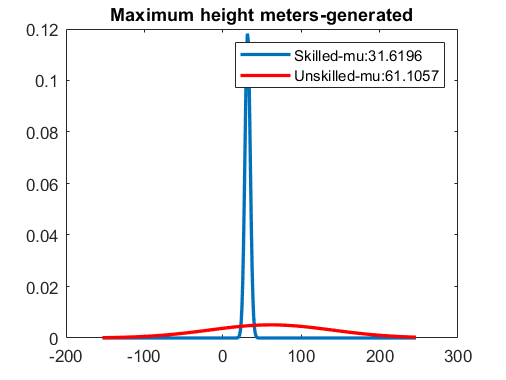

[split, generated] = generateData(data, data.max_height_m, 200);                            % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                      % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                      % subset division 1
unskilled = generated(split=="Unskilled");                                                  % subset division 2
t_test_tail(skilled,unskilled,'left');                                                      % t-test tail left (x < y)

    "Null h:Equal mean/Alternative h:x < y"

    "Reject null hypothesis, p:0.00011012"



#### Average speed

We assume unskilled pilots will take the drone at an average higher speed due to unawareness of safety issues.

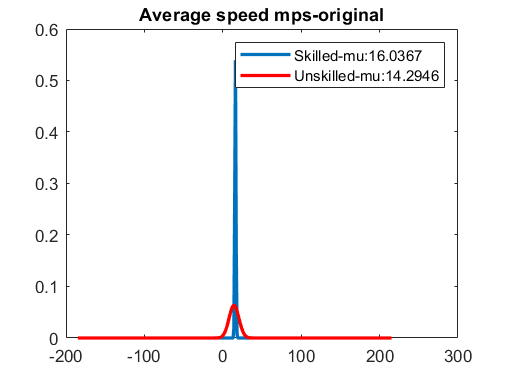

var_title = 'Average speed mps';                                                            % variable analysed
analyseDistribution(data.avg_speed_mps, data.skilled, strcat(var_title,'-original'));       % analyse the distribution of original values

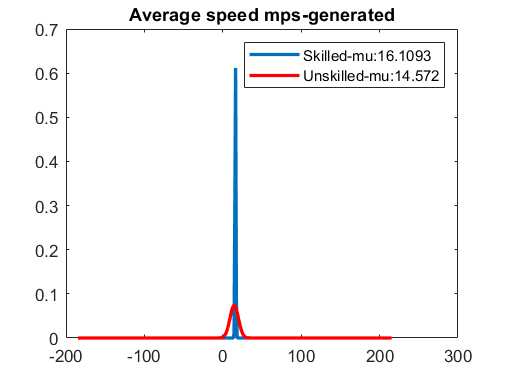

[split, generated] = generateData(data, data.avg_speed_mps, 200);                           % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                      % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                      % subset division 1
unskilled = generated(split=="Unskilled");                                                  % subset division 2
t_test_tail(skilled,unskilled,'left');                                                      % t-test tail left (x < y)

    "Null h:Equal mean/Alternative h:x < y"

    "Do not reject null hypothesis, p:0.99746"



#### Maximum speed

We assume unskilled pilots will take the drone at an higher maximum speed due to unawareness of safety issues.

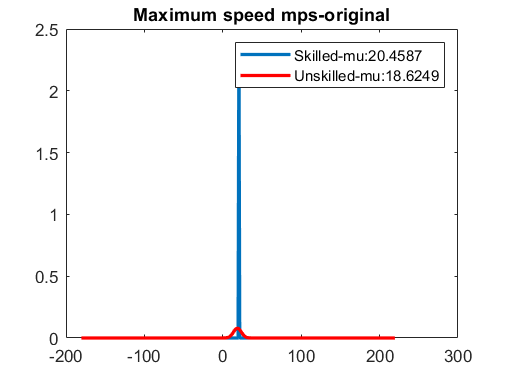

var_title = 'Maximum speed mps';                                                            % variable analysed
analyseDistribution(data.max_speed_mps, data.skilled, strcat(var_title,'-original'));       % analyse the distribution of original values

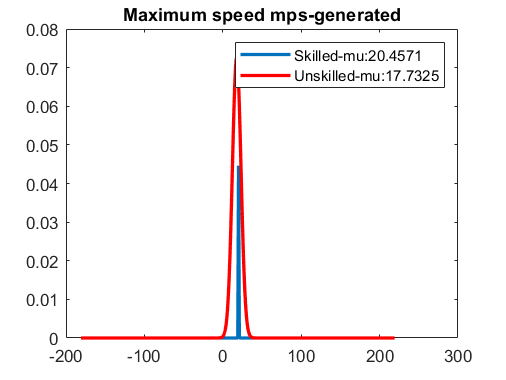

[split, generated] = generateData(data, data.max_speed_mps, 200);                           % generate more samples
analyseDistribution(generated, split, strcat(var_title,'-generated'));                      % analyse the distribution of sampled values

skilled = generated(split=="Skilled");                                                      % subset division 1
unskilled = generated(split=="Unskilled");                                                  % subset division 2
t_test_tail(skilled,unskilled,'left');                                                      % t-test tail left (x < y)

    "Null h:Equal mean/Alternative h:x < y"

    "Do not reject null hypothesis, p:1"



vvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvv

----------------------------------------------------------------------------------------------------------------

----------------------------------------------------------------------------------------------------------------

----------------------------------------------------------------------------------------------------------------

vvvvvvvvvvvvvvvvvvvvvvvvvv    Functions    vvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvvv 

Function to analyse and plot the 2 grouped distributions of values based on the given indexing (e.g. with split being skilled and unskilled the first distribution will be of the values labeled as "skilled" and the second distribution as "unskilled").

function [] = analyseDistribution(values, split, str_title)
    [pdca,gn,~] = fitdist(values,'Normal','By',split);
    s1 = pdca{1};
    s2 = pdca{2};
    mu = (s1.mu + s2.mu) / 2 ;
    xvalues = mu-200:1:mu+200;
    s1pdf = pdf(s1, xvalues);
    s2pdf = pdf(s2, xvalues);
    leg = [strcat(string(gn(1)),"-mu:",num2str(s1.mu)) ...
        strcat(string(gn(2)),"-mu:",num2str(s2.mu))];
    figure
    plot(xvalues,s1pdf,'LineWidth',2)
    hold on
    plot(xvalues,s2pdf,'Color','r','LineWidth',2)
    legend(leg,'Location','NorthEast')
    hold off
    title(str_title);
end

Function to generate data based on the distribution of the values in the skilled and in the unskilled subset, will return a index array for the two subsets (e.g. ["skilled" * n/2, "unskilled" * n/2]), and the values array split accordingly to the indexing (e.g. the first n/2 values will be drew from the distribution of the "skilled" original samples and the last n/2 from the "unskilled" original sample population).

function [split, generated] = generateData(data, values, N)
    % gather values for skilled and unskilled subsets
    skilled_values = values(data.("skilled") == "Skilled");
    unskilled_values = values(data.("skilled") == "Unskilled");

    % generate samples with replacement from given population distribution
    generated_skilled = randsample(skilled_values, N/2, true);
    generated_unskilled = randsample(unskilled_values, N/2, true);
    
    % combine new indexing and generated values
    split = cat(1, repelem("Skilled",N/2).', repelem("Unskilled",N/2).');
    generated = cat(1 , generated_skilled, generated_unskilled);
end

Function to add skilled label column based on flight hours, pilots gets labeled as skilled if the total flight time is above the average.

function data = divideByFlightHrs(data)
    avg = mean(data.flight_hrs);
    skilled = data.flight_hrs > avg;
    data.skilled(skilled)="Skilled";
    data.skilled(~skilled)="Unskilled";
end

Function to perform all tests we have

function [] = perform_tests(skilled, unskilled)
    t_test(skilled, unskilled, true);
    t_test(skilled, unskilled, false);
    t_test_tail(skilled, unskilled, 'left');
    t_test_tail(skilled, unskilled, 'right');
    f_test(skilled, unskilled);
    f_test_tail(skilled, unskilled, 'left');
    f_test_tail(skilled, unskilled, 'right');
end

Function to perform two-sample *F*-test for equal variances, returns a test decision for the null hypothesis that the data in `x` and `y` comes from normal distributions with the same variance, using the [two-sample *F*-test](https://nl.mathworks.com/help/stats/vartest2.html#btttvph). The alternative hypothesis is that they come from normal distributions with different variances. The result `h` is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise.

function [h, p] = f_test(x, y)
    [h, p] = vartest2(x,y);
    display_hypothesis("Equal variance","Unequal variance", h,p)
end

Function to perform two-sample *F*-test for equal variances, returns a test decision for the null hypothesis that the data in `x` and `y` comes from normal distributions with the same variance, using the [two-sample *F*-test](https://nl.mathworks.com/help/stats/vartest2.html#btttvph). 

The alternative hypothesis that the population mean for x is less than the population mean for y (tail left) , or mean x is greater than mean y (tail right) .The result `h` is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise.

function [h, p] = f_test_tail(x, y, tail)
    [h, p] = vartest2(x,y, 'Tail',tail);
    if tail == "left"
        altern = "x < y";
    else 
        altern = "x > y";
    end
    display_hypothesis("Equal variance",altern, h,p)
end

Function to perform t-test for the null hypothesis that the data in x and y comes from independent random samples from normal distributions with equal means.

The alternative hypothesis is that the data comes from populations with unequal means. The result `h` is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise.

function [h, p] = t_test(x, y, var_equal)
    if var_equal
        [h, p] = ttest2(x,y, 'Vartype','equal');
    else 
        [h, p] = ttest2(x,y, 'Vartype','unequal');
    end
    display_hypothesis("Equal mean","Unequal mean", h,p)
end

Function to perform t-test for the null hypothesis that the data in x and y comes from independent random samples from normal distributions with equal means.

The alternative hypothesis that the population mean for x is less than the population mean for y (tail left) , or mean x is greater than mean y (tail right). The result `h` is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise.

function [h, p] = t_test_tail(x, y, tail) 
    [h, p] = ttest2(x,y, 'Tail',tail);
    if tail == "left"
        altern = "x < y";
    else 
        altern = "x > y";
    end
    display_hypothesis("Equal mean",altern, h,p)
end

Function to display whether to reject or do not reject null hypothesis

function[] = display_hypothesis(null,altern, h, p)
    display(strcat("Null h:",null,"/Alternative h:",altern));
    if h==0
       display(strcat("Do not reject null hypothesis, p:", num2str(p)));
    else 
       display(strcat("Reject null hypothesis, p:", num2str(p)));
    end
end

% data.("distance m") = str2double(replace(data.("distance m"),",", "."));
% data.("max speed mps") = str2double(replace(data.("max speed mps"),",", "."));
% data.("avg speed mps") = str2double(replace(data.("avg speed mps"),",", "."));
% data.("max height m") = str2double(replace(data.("max height m"),",", "."));
% data.("avg height m") = str2double(replace(data.("avg height m"),",", "."));


% Divide by flight hrs
% skilled = data(data.("flight hrs") >= 100,:)
% unskilled = data(data.("flight hrs") < 100 ,:)